tau=0.00564

tau = 0.0056

lm=1

lm = 1

cw=0.000591

cw = 5.9100e-04

xec= 0.936

xec = 0.9360

rl= 7.884

rl = 7.8840

rw= 10.666

rw = 10.6660


f_=linspace(1,7,15)

f_ =     1.0000    1.4286    1.8571    2.2857    2.7143    3.1429    3.5714    4.0000    4.4286    4.8571    5.2857    5.7143    6.1429    6.5714    7.0000


f=10.^f_

f = 1.0e+07 *

    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0004    0.0010    0.0027    0.0072    0.0193    0.0518    0.1389    0.3728    1.0000



s=2i*pi.*f*tau+1

s = 1.0e+05 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0001i   0.0000 + 0.0002i   0.0000 + 0.0005i   0.0000 + 0.0013i   0.0000 + 0.0035i   0.0000 + 0.0095i   0.0000 + 0.0255i   0.0000 + 0.0684i   0.0000 + 0.1835i   0.0000 + 0.4924i   0.0000 + 1.3210i   0.0000 + 3.5437i



%Z=s./(1-exp(-s.*xec./lm))./(2i*pi*f*cw*lm)
Z1=lm*rl./sqrt(s)%.*(1-exp(-s.*xec./lm))

Z1 =    7.5435 - 1.2971i   6.2329 - 2.4899i   3.9353 - 2.6840i   2.2682 - 1.9608i   1.3352 - 1.2644i   0.8024 - 0.7863i   0.4869 - 0.4832i   0.2966 - 0.2957i   0.1809 - 0.1807i   0.1104 - 0.1104i   0.0674 - 0.0674i   0.0412 - 0.0411i   0.0251 - 0.0251i   0.0153 - 0.0153i   0.0094 - 0.0094i


Y2=s/rw

Y2 = 1.0e+04 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0001i   0.0000 + 0.0002i   0.0000 + 0.0005i   0.0000 + 0.0012i   0.0000 + 0.0033i   0.0000 + 0.0089i   0.0000 + 0.0239i   0.0000 + 0.0641i   0.0000 + 0.1721i   0.0000 + 0.4617i   0.0000 + 1.2385i   0.0000 + 3.3224i


Z=1./(1./Z1+Y2)

Z =    4.2321 - 1.0530i   3.1061 - 1.9323i   1.3418 - 1.7948i   0.4030 - 1.0011i   0.1056 - 0.4527i   0.0261 - 0.1872i   0.0062 - 0.0740i   0.0015 - 0.0286i   0.0003 - 0.0109i   0.0001 - 0.0041i   0.0000 - 0.0015i   0.0000 - 0.0006i   0.0000 - 0.0002i   0.0000 - 0.0001i   0.0000 - 0.0000i


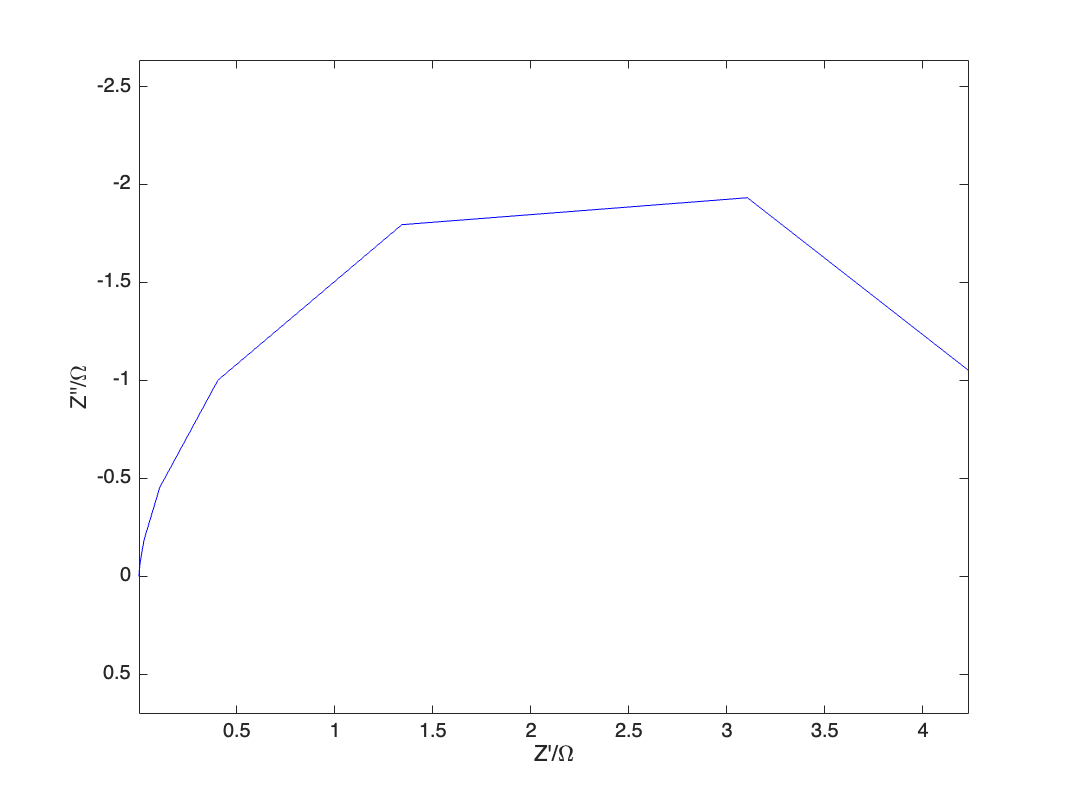

plotcplx(Z)

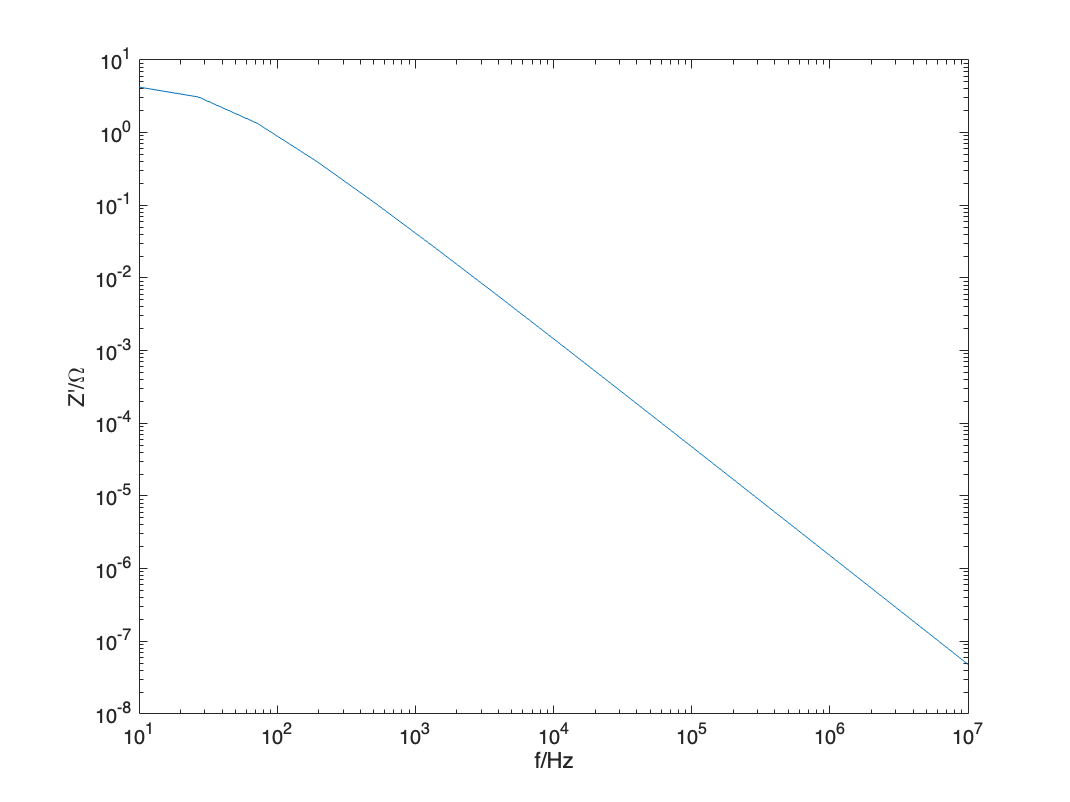

plotreal(f,Z)